Date: 28 May 2025

% Requires

Statistics and Machine Learning Toolbox

Curve Fitting Toolbox

## Fig 1: Demonstration of the effect of mistakes in O'Brien et al., 2025

setExportFig=0; 
outputFolder = 'H:\My Drive\Boox\Papers\My Papers\Comment on Connor 2025\Figures\';

nSamples  = 200000;
nEnsembles = 1;


Creating a toy-model 

X = random('Lognormal',0.1,0.5,1,nSamples); % True value that is log-normally distributed
W = X; % Copy of the variable

noiseAmp = 0.4; % Parameter that determines the magnitude of the uncertainty

W1 = W + noiseAmp.*W.^2.*random('Normal',0,1,1,nSamples); % Uncertain measurement 1
X1 = X + noiseAmp.*X.^2.*random('Normal',0,1,1,nSamples); % Uncertain measurement 2
% The uncertainty is Gaussian, but increases as the square of the magnitude
% of the true value

XBin = linspace(0,max(X1),100);

Non-linear regression of different random variables

EWgX can be translated to the conditional expectation of W given X ($\langle W|X\rangle$)

EWgX = create_curve(W',X',XBin);    % Relation between the true value and measurement if it had no uncertainty (45 degree line)
EW1gX = create_curve(W1',X',XBin);  % Expectation of the erroneous measurement given true value
EWgX1 = create_curve(W',X1',XBin);  % Expectation of the true value given the erroneous measurement
EW1gX1 = create_curve(W1',X1',XBin); % Expectation of an erroneous measurement with another erroneous measurement


Figure shows the summar of the relation between the measurement and true value for our assumed error model. 

They show a log-normal distribution, heteroskedatic uncertainty, and a non-linear regression bias that makes true value

vary with the erroneous measurement. 

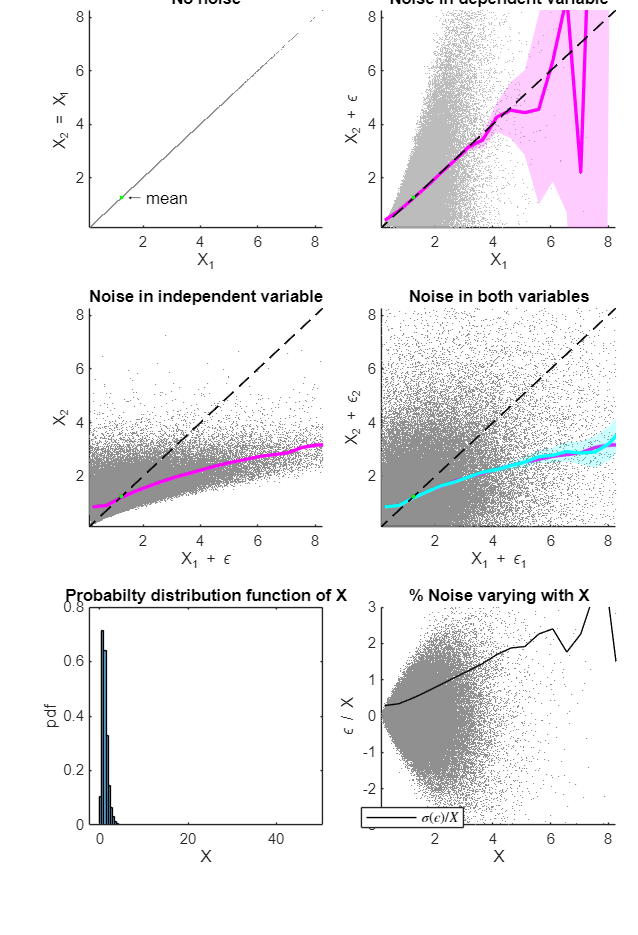

f2 = figure;
resize_figure(f2,220,150);
plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,'linear');

if setExportFig
export_fig([outputFolder,'FigureS1.png'], ...
    '-r600','-png','-nocrop',f2);
export_fig([outputFolder,'FigureS1.pdf'], ...
    '-r600','-pdf','-nocrop',f2);
end

Section 3.1 Converting the random variables into log-space, and log-linear regression bias correction

lX1 = real(log(X1));
lX = real(log(X));
lXBin = linspace(min(lX1),max(lX1),100);
ElXglX1 = create_curve(lX',lX1',lXBin); % True value in log space given log of erroneous measurement

options = fitoptions('Method', 'LinearLeastSquares','Robust','LAR');
    fit_LLSE_l = fit(lX1',lX','poly1',options); % Doing a log-linear fit 


%% Finding the best linear predictor and regressing W with that 
    sigma_lX = std(lX);
    sigma_U = std(lX1-lX);
    lamda = sigma_lX^2./(sigma_lX^2+sigma_U^2);
    
    lX1blp = (1-lamda).*mean(lX) + lamda*lX1; %Best linear predictor, with correct measure of uncertainty in log-space

    fit_LLSE_l2 = fit(lX1blp',lX','poly1',options);

Section 3.2 Modifying the log-linear regression bias correction by calculating bias at every measurement and

Section 3.3. Error in implementing conversion to log space

 %% Correcting each X1, by assuming different lambdas calculated from different uncertainties of X1 
    Ui = abs(lX1-lX);
    [xindx, ~] = discretize(lX1(:),lXBin);
    for i = 1:max(xindx)
        % meanUi_lX(i) = nanmean(Ui(xindx==i));
        sigmalXglX1_correct(i) = nanstd(lX(xindx==i)); %% Section 3.2 log(sigma)
        sigmalXglX1(i) = log((nanstd(X(xindx==i)))); %% Mistake in Section 3.3 sigma(log)
    end

    sigmaUi_lX1i = interp1(lXBin(1:end-1),sigmalXglX1,lX1);
    sigmaUi_lX1i_correct = interp1(lXBin(1:end-1),sigmalXglX1_correct,lX1);
    lamdai = sigma_lX^2./(sigma_lX^2+sigmaUi_lX1i.^2);
    lamdai_correct = sigma_lX^2./(sigma_lX^2+sigmaUi_lX1i_correct.^2);
    
    lX1blpi = (1-lamdai).*mean(lX)+lamdai.*lX1;
    lX1blpi_correct = (1-lamdai_correct).*mean(lX)+lamdai_correct.*lX1;


    
ElXglX1blp = create_curve(lX',lX1blp',lXBin);    
ElXglX1blpi = create_curve(lX',lX1blpi',lXBin);    
EXgX1blp = create_curve(exp(lX)',exp(lX1blp)',XBin);  
 
EXgX1blpi = create_curve(exp(lX)',exp(lX1blpi)',XBin);   
EXgX1blpi_correct = create_curve(exp(lX)',exp(lX1blpi_correct)',XBin);   

%% Bringing back from log to linear space

f1 = figure;
resize_figure(f1,150,150);
scatter(X1,X,0.5,0.5.*[1 1 1],'filled'); 
ylim([0,12]);
xlim([0,12]);
set(gca,'XScale','linear','YScale','linear');
title('X vs. X+\epsilon')
% title('Noise in independent variable');
xlabel('W = X + \epsilon or W^c');
ylabel('X');
hold on;
plot_curve(EWgX1,'m'); % Non-linear regression, showing the regression bias

hold on;

plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1); % 45 degree line

hold on;

plot_curve(EXgX1blp,'r',0.5); % Section 3.1, log-linear regression bias calibration

plot_curve(EXgX1blpi_correct,'c',0.5); % Section 3.2, modified log-linear regression bias with bias correction for each measurement

plot_curve(EXgX1blpi,'b'); % Section 3.3, compounded with the error in calculating the uncertainty, the final regression calibration of O'Brien et al., 2025


## Section 4: Non-linear regression calibration

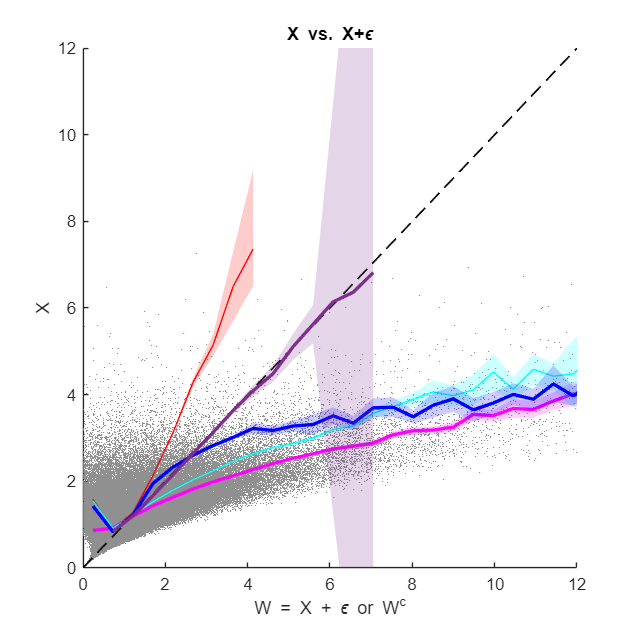

W2C=interp1(EWgX1.XBins,EWgX1.YgX,X1(:),'linear')'; % Regression calibration; Stretching the X-axis according to the regression function <X|X*>
EWgW2C = create_curve(W',W2C',XBin);
hold on;
plot_curve(EWgW2C,[0.4940 0.1840 0.5560]); % Section 4: The result of doing non-linear regression calibration using our method. 


if setExportFig
export_fig([outputFolder,'Figure1.png'], ...
    '-r600','-png','-nocrop',f1);
export_fig([outputFolder,'Figure1.pdf'], ...
    '-r600','-pdf','-nocrop',f1);
end

## **Functions**

function plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,Scale)
    tiledlayout(3,2,'TileSpacing',"compact");
    
    nexttile
    scatter(X,W,0.5,0.5.*[1 1 1],'filled');
    set(gca,'XScale',Scale,'YScale',Scale);
    hold on;
    plot(mean(X),mean(W),'.g');
    text(mean(X),mean(W),' 🠐 mean',"HorizontalAlignment","left");
    title('No noise');
    xlabel('X_1');
    ylabel('X_2 = X_1');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    %% Regression curve with noise only on W
    nexttile
    
    scatter(X,W1,0.5,[0.7 0.7 0.7],'filled',"o");
    hold on;
    plot_curve(EW1gX,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale',Scale,'YScale',Scale);
    title('Noise in dependent variable');
    xlabel('X_1');
    ylabel('X_2 + \epsilon');
    
    %% Regression curve with noise only on X
    nexttile
    
    scatter(X1,W,0.5,0.5.*[1 1 1],'filled');
    hold on;
    plot_curve(EWgX1,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale',Scale,'YScale',Scale);
    title('X_1 vs. X_1+\epsilon')
    title('Noise in independent variable');
    xlabel('X_1 + \epsilon');
    ylabel('X_2');
    %% Regression curve with noise in X & W
    
    nexttile
    
    scatter(X1,W1,0.5,0.5.*[1 1 1],'filled');
    hold on;
    plot_curve(EWgX1,'m');
    hold on;
    plot_curve(EW1gX1,'c');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale',Scale,'YScale',Scale);
    title('X_1+\epsilon vs. X_2+\epsilon')
    title('Noise in both variables');
    xlabel('X_1 + \epsilon_1');
    ylabel('X_2 + \epsilon_2');
    
    nexttile
    histogram(X,'BinEdges',XBin,'Normalization',"pdf");
    xlabel('X');
    ylabel('pdf');
    title('Probabilty distribution function of X')
    
    ax2=nexttile;
    scatter(X,(X1-X)./X,0.5,0.5.*[1 1 1],'filled');
    EegX = create_curve((X1'-X'),X',XBin);
    hold on;
    p1=plot(EegX.XBins,EegX.stdYgX./abs(EegX.XBins),'k');
    legend(ax2,p1,'$\sigma(\epsilon)/X$','interpreter','latex','Location','best');
    ylim([-3 3]);
    xlim([min(X),max(X)]);
    xlabel('X');
    ylabel('\epsilon / X');
    title('% Noise varying with X')
end

function p = plot_curve(curve, color, lw)

if nargin<3
    lw = 2;
end

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX, 'Color', color,'LineWidth',lw);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
    hold on;
    X2 = [x, fliplr(x)];
    inBetween = [ci(:,1)', fliplr(ci(:,2)')];
    fill(X2,inBetween,color,'LineStyle','none','FaceAlpha',alpha);
end

function curve = create_curve(Y, X, Ei)
% Y - first variable, X - second variable, Ei - bin array
if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);

for i = 1:max(xindx)
    curve.YgX(i) = nanmean(Y(xindx==i));
    curve.stdYgX(i) = nanstd(Y(xindx==i));
    curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
    curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
    curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
    curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
    curve.XBins(i) = 0.5*(E(i)+E(i+1));
end

curve.E = E; 

end


function resize_figure( figureHandle, vert, horz )
%% resize_figure.m Resizes figure into a standard paper size
%--------------------------------------------------------------------------
% Input
%------
% figureHandle
% vert - Vertical page size in mm (Default Letter Size)
% horz - Horizontal page size in mm (Default Letter Size)

if nargin<3 || isempty(horz)
    horz = 215.9;
end
if nargin<2 || isempty(vert)
    vert = 279.4;
end

% Centimeter Units
X = horz/10;
Y = vert/10;
xMargin = 0;
yMargin = 0;
xSize = X - 2*xMargin;
ySize = Y - 2*yMargin;

% Figure size displayed on screen
movegui(figureHandle, 'center');
set(figureHandle,'color','w');
set(figureHandle, 'Units', 'centimeters', 'Position', [0 0 xSize ySize])
end

function B = interp_nans(A)
%% interp_nans.m This function removes nan by interpolating along altitude
%--------------------------------------------------------------------------
% Input
%------
% A - Input altitude vs. time matrix [nh x nT]
%--------------------------------------------------------------------------
% Output
%-------
% B - Interpolated altitude vs. time matrix, along the altitude directon
%     with nans removed [nh x nT]
%--------------------------------------------------------------------------
% Modified: 17th Jan 2018 
% Created : 25th Sep 2016
% Author  : Nithin Sivadas
% Ref     : 
%--------------------------------------------------------------------------
     
	x=1:1:size(A,1);
    
	for ty=1:1:size(A,2)
	
	    y=A(:,ty);
	    xi=x(find(~isnan(y)));
	    yi=y(find(~isnan(y)));
	   
        if sum(isnan(y))< size(A,1)-2
        B(:,ty)=interp1(xi,yi,x,'linear','extrap');
        else
        B(:,ty)=A(:,ty);
        end
	
    end

	[isThereNAN, totalNAN] = check_nan(B);

end

function [isThereNAN, totalNAN] = check_nan(thisArray)
%% check_nan.m Check if there is any nan values in the given array
%--------------------------------------------------------------------------
% Input
%------
% thisArray : An array or a matrix
%--------------------------------------------------------------------------
% Output
%-------
% isThereNAN : A boolean variable, True => there is nan values in the
%              array, and False => there is no nan values in the array
% totalNAN   : The total number of NAN values
%
%--------------------------------------------------------------------------
% Modified: 22nd Sep 2016 
% Created : 22nd Sep 2016
% Author  : Nithin Sivadas
% Ref     :
%--------------------------------------------------------------------------

thisArrayNAN = isnan(thisArray);
totalNAN = sum(thisArrayNAN(:));

    if totalNAN>0
        isThereNAN = true;
    else
        isThereNAN = false;
    end

    if isThereNAN==true
        warning(['There are ',num2str(totalNAN),...
        ' nan values in your data. The results may not be accurate.']);
    end
    
end
%%

# External Functions

Acknowledging the use of these external functions: 

- F. Carr (2022). Orthogonal Linear Regression (https://www.mathworks.com/matlabcentral/fileexchange/16800-orthogonal-linear-regression), MATLAB Central File Exchange. Retrieved April 19, 2022.

 
function [p] = linortfit2(xdata, ydata)
% LINORTFIT2  Fit a line to data by ORTHOGONAL least-squares.
%    P = LINORTFIT2(X,Y) finds the coefficients of a 1st-order polynomial
%    that best fits the data (X,Y) in an ORTHOGONAL least-squares sense.
%    Consider the line P(1)*t + P(2), and the minimum (Euclidean) distance
%    between this line and each datapoint [X(i) Y(i)] -- LINORTFIT2 finds
%    P(1) and P(2) such that the sum of squared distances is minimized.
if ~isequal(size(xdata), size(ydata))
    error('linortfit2:XYSizeMismatch',...
          'X and Y vectors must be the same size.');
end
[N,C] = linortfitn([xdata(:) ydata(:)]);
% The hyperplane given by N * [x; y] + C == 0 is optimal.
% Convert to the form  y = p(1)*x + p(2), just like polyfit(xdata,ydata,1).
p = - [N(1)  C] / N(2);
end

function [hyperplane_normal, hyperplane_offset] = linortfitn(data)
% LINORTFITN  Fit a line to data by ORTHOGONAL least-squares.
%    [N,C] = LINORTFITN(DATA) finds the coefficients of a hyperplane (in
%    Hessian normal form) that best fits the data in an ORTHOGONAL
%    least-squares sense.  Consider the hyperplane
%       H = {x | dot(N,x) + C == 0},
%    and the minimum (Euclidean) distance between this hyperplane and each
%    datapoint DATA(i,:) -- LINORTFITN finds N and C such that the sum of
%    squared distances is minimized.
[M,N] = size(data);
if M <= N,
    error('linortfitn:DegenerateProblem',...
        'There are fewer datapoints than dimensions: the data is perfectly fit by a hyperplane.');
end
[U,S,V] = svd(data - repmat(mean(data),M,1), 0);
hyperplane_normal = V(:,end);
hyperplane_offset = - mean(data * hyperplane_normal);
end